I = imread('frame.png');
gray_I = rgb2gray(I);
cropped = gray_I(300:700,1300:1700);
%imshow(cropped)
size(cropped)

ans =    401   401


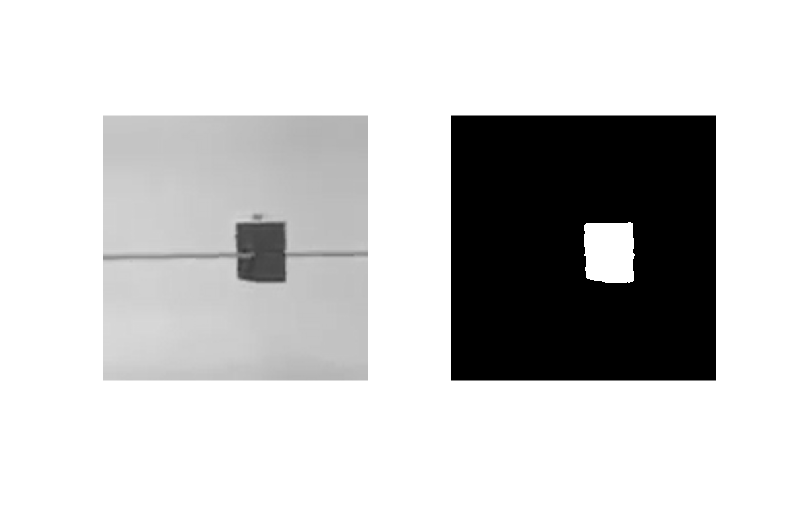

bw_I = im2bw(cropped,0.52);
bw_I = ~bw_I;
subplot(121),imshow(cropped)
bw_I = bwareaopen(bw_I,1000);
subplot(122),imshow(bw_I)

%se1 = strel('square',15);
%er = imerode(bw_I,se1);
%dil = imdilate(er,se1);
%final = dil(50:350,800:1200);
%figure, imshow(dil)
%s = regionprops(final,'Centroid');
%s.Centroid;